sampling_frequency = 100; % in Hz

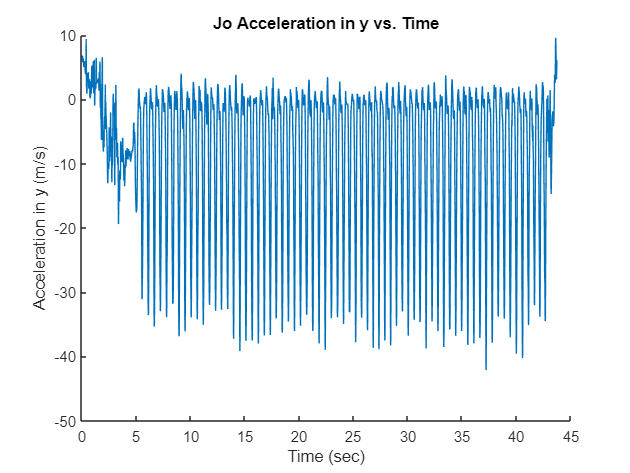

[JoMotionData] = ParseMatlabApp('data/jo_tramp.mat');
Jo_A = getfield(JoMotionData, 'Accel');
Jo_t = getfield(JoMotionData,'t_Accel');
Jo_Ay = Jo_A(:,2);

figure; clf; hold on;
plot(Jo_t, Jo_Ay)
title('Jo Acceleration in y vs. Time');
xlabel('Time (sec)');
ylabel('Acceleration in y (m/s)');

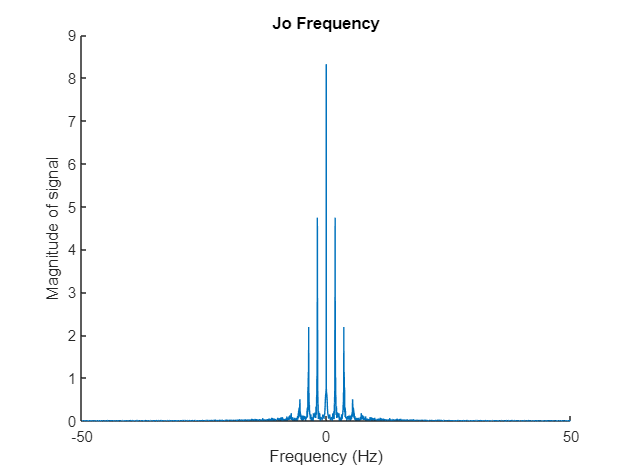

x = Jo_Ay;
Fs = sampling_frequency;
if(mod(length(x),2) ~=0)
    x = x(1:end-1);
end

figure; clf; hold on;
plot(linspace(-Fs/2, Fs/2-Fs/length(x),length(x)), 1/length(x)*fftshift(abs(fft(x))))
ylabel('Magnitude of signal');
xlabel('Frequency (Hz)');
title('Jo Frequency');

bpm_jo = 1.82*60;
display(bpm_jo)

bpm_jo = 109.2000

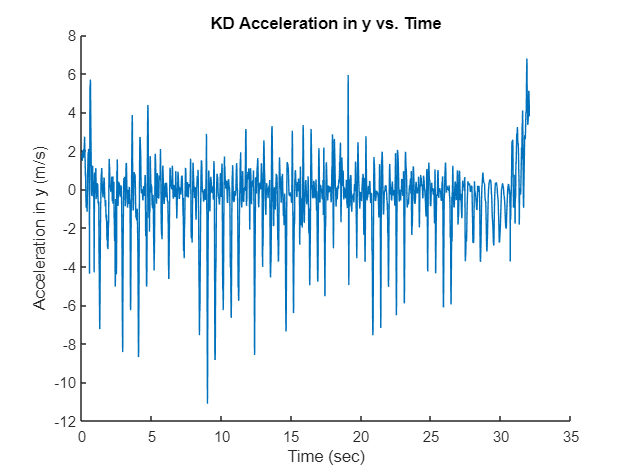

[KDMotionData] = ParseMatlabApp('data/kd_tramp.mat');
KD_A = getfield(KDMotionData, 'Accel');
KD_t = getfield(KDMotionData,'t_Accel');
KD_Ay = KD_A(:,2);

figure; clf; hold on;
plot(KD_t, KD_Ay)
title('KD Acceleration in y vs. Time');
xlabel('Time (sec)');
ylabel('Acceleration in y (m/s)');

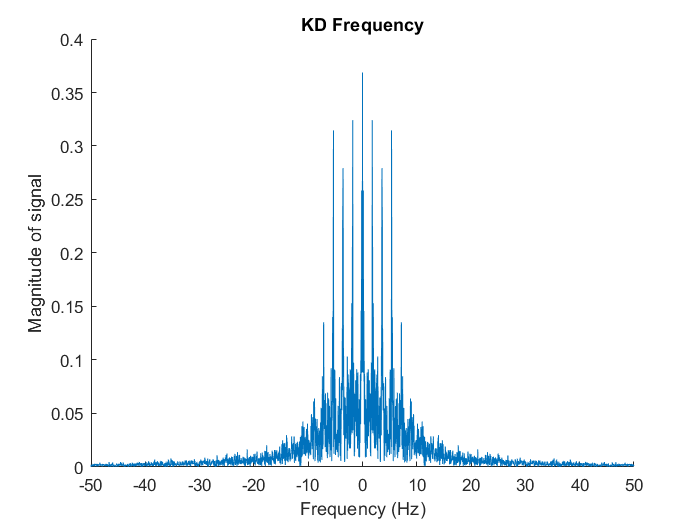

x = KD_Ay;
Fs = sampling_frequency;
if(mod(length(x),2) ~=0)
    x = x(1:end-1);
end

figure; clf; hold on;
plot(linspace(-Fs/2, Fs/2-Fs/length(x),length(x)), 1/length(x)*fftshift(abs(fft(x))))
ylabel('Magnitude of signal');
xlabel('Frequency (Hz)');
title('KD Frequency');

bpm_kd = 1.79*60;
display(bpm_kd)

bpm_kd = 107.4000